n = -3:6

n =     -3    -2    -1     0     1     2     3     4     5     6




h = [-1 2 -1 0 0 0 0 0 0 0]

h =     -1     2    -1     0     0     0     0     0     0     0


x = [0 0 0 1 1 0 1 1 0 0]

x =      0     0     0     1     1     0     1     1     0     0


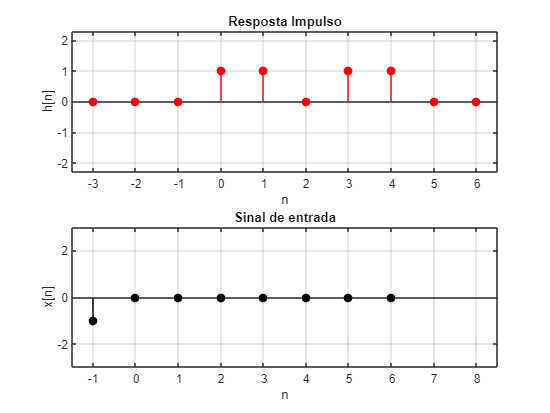


subplot(2,1,1)
stem(n,x,"filled","r")
xlabel("n")
ylabel("h[n]")
title("Resposta Impulso")
ylim([-2.3 2.3])
xlim([-3.5 6.5])
grid on
subplot(2,1,2)
stem(n,h,"filled","k")
xlabel("n")
ylabel("x[n]")
title("Sinal de entrada")
ylim([-3 3])
xlim([-1.5 8.5])
grid on

%%Convolução na mao
y = []


y =

     []



hk = h

hk =     -1     2    -1     0     0     0     0     0     0     0


N = length(x)

N = 10


for i=1 : N-1

%vamos chamar x[k] = x
%h[n-k] = hk -> h(espelhado)

y(i)= sum(x.*hk)
hk = shift_um(hk)

end

y = 0

hk =      0    -1     2    -1     0     0     0     0     0     0


y =      0    -1


hk =      0     0    -1     2    -1     0     0     0     0     0


y =      0    -1     1


hk =      0     0     0    -1     2    -1     0     0     0     0


y =      0    -1     1     1


hk =      0     0     0     0    -1     2    -1     0     0     0


y =      0    -1     1     1    -2


hk =      0     0     0     0     0    -1     2    -1     0     0


y =      0    -1     1     1    -2     1


hk =      0     0     0     0     0     0    -1     2    -1     0


y =      0    -1     1     1    -2     1     1


hk =      0     0     0     0     0     0     0    -1     2    -1


y =      0    -1     1     1    -2     1     1    -1


hk =     -1     0     0     0     0     0     0     0    -1     2


y =      0    -1     1     1    -2     1     1    -1     0


hk =      2    -1     0     0     0     0     0     0     0    -1



%stem(n,y)


%%Parte 2

h = [-1 2 -1 0 0 0 0 0 0 0]

h =     -1     2    -1     0     0     0     0     0     0     0


x = [0 1 1 0 1 1 0 0 0 0]

x =      0     1     1     0     1     1     0     0     0     0


N = length(x)

N = 10

M = 3

M = 3

n = -1:8

n =     -1     0     1     2     3     4     5     6     7     8



%gerar matriz com os h deslocados

hk = k 

Unrecognized function or variable 'k'.

for i=1:N-1
    
    h_deslocados(:,i) = hk
    subplot(N-M,1,i)
    stem(hk)
    hk = shift_um(hk)

end


function B=shift_um(A)
B = [A(end) A(1:end-1)];
end